# Transient simulation on the RDC surrogate model 

## 1 Set parameters

addpath(genpath(fileparts(pwd)))
global Ks Kx M gamma nx dx
dt = 0.001;                %time step
save_every = 100;          %save the results every 100 steps (or other paramters) 
L = 24;                    %circumference of the combustor
nx = 2400;                 %number of grids in the 1D domain
gamma = 1.29;              %fixed specific heat ratio for H2-Air
tend = 100;                %end time for simulation
s = 0;                     %speed for coordinate frame, normally set as 0 or speed of detonation wave.
beta = 0.08;               %Ratio of convective time scale to the mixing time scale,see Table 1 in the paper.
[Ks,Kx,M] = getStiff(L,nx);%get difference matrix
dx = L/nx;
xc = linspace(0+0.5*dx,24-0.5*dx,nx);
t = 0:dt:tend;nt = length(t);
tsave = 0:save_every*dt:tend;

## 2 Set initial conditions

p0 = 0.5; T0 = 1.0;
rho0 = p0/T0; z0 = 0.0;
q0 = zeros(4,nx);
q0(1,:) = rho0;
q0(2,:) = 0*rho0;                         
q0(3,:) = p0/(gamma - 1);
q0(4,:) = rho0*z0;
output_index = 1;
output_times = round((nt-1)/save_every);
q1 = zeros(nx,output_times+1);q2 = zeros(nx,output_times+1);q3 = zeros(nx,output_times+1);q4 = zeros(nx,output_times+1);
q1(:,1) = q0(1,:)';q2(:,1) = q0(2,:)';q3(:,1) = q0(3,:)';q4(:,1) = q0(4,:)';
q_last = [q1(:,1);q2(:,1);q3(:,1);q4(:,1)];

## 3 Main Loop

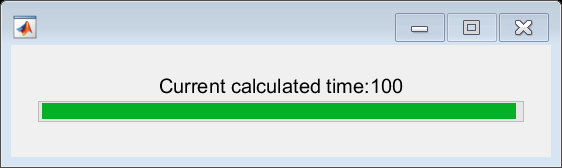

h = waitbar(0, 'Initializing...');
for i = 1:nt-1
    Da = ones(nx,1)*128.7;
    Tc = 1.05;
    %if t<10, set sinusoidal profile for propellants (z)
    if t(i+1) < 10
        beta_sim = 0.0;
        z = 0.5*sin(2*pi*xc/L)' + 0.5;
        q_last(3*nx+1:4*nx) = q_last(1:nx).*z;
    end
    
    %During 10<t<10.20, ignite region [0,3] by set Da a high value
    if t(i+1)>=10 && t(i+1)<=10.2
        Da(xc > 0 & xc < 3) = 2000;
        Tc = 0.99;
    end

    if t(i+1)>10.2
        beta_sim = beta;
    end
    
    %two-step Runge-Kutta method
    qt = q_last + dqdt(q_last,s,beta_sim,Da,Tc)*dt;
    q_next = 0.5*q_last + 0.5*(qt + dt*dqdt(qt,s,beta_sim,Da,Tc));

    if mod(i,save_every)==0
        output_index = output_index + 1;
        q1(:,output_index) = q_next(1:nx);q2(:,output_index) = q_next(nx+1:2*nx);
        q3(:,output_index) = q_next(2*nx+1:3*nx);q4(:,output_index) = q_next(3*nx+1:4*nx);
        waitbar(i / nt, h, ['Current calculated time:', num2str(i*dt)]);
    end
    q_last = q_next;
end

## 4 Plot results

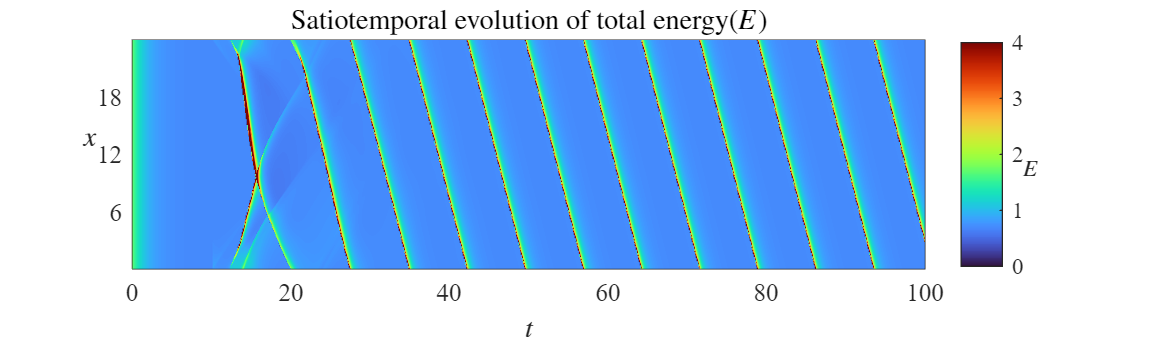

figure('Position', [100 100 1000 300]);
pcolor(tsave,xc,q3),shading interp,colormap('turbo')
clim([0,4])
h = colorbar;
h.Label.String = '$E$';
h.Label.Interpreter = 'latex';
h.Label.Rotation = 0;
xl = xlabel('$t$');yl = ylabel('$x$','Rotation',0);
yticks([0 6 12 18 24])
set(xl,'Interpreter','latex');set(yl,'Interpreter','latex');
set(gca,'fontName','Times New Roman')
set(gca,'fontSize',10)
tl = title('Satiotemporal evolution of total energy($E$)');
set(tl,'Interpreter','latex')